clear all; close all;
addpath("Kinematics")
addpath("Trajectory")

pos(1) = ArmPos;
pos(1).phiX = 0.22;
pos(1).phiZ = -0.2;
pos(1) = pos(1).phiZXtoFullpos(false);
pos(2) = ArmPos;
pos(2).phiX = 0.3;
pos(2).phiZ = 0.2;
pos(2) = pos(2).phiZXtoFullpos(false);


n = 2048;
r = linspace(pos(1).D(1), pos(2).D(1), n)

r =   246.4138  246.4024  246.3909  246.3794  246.3679  246.3564  246.3449  246.3334  246.3220  246.3105  246.2990  246.2875  246.2760  246.2645  246.2530  246.2416  246.2301  246.2186  246.2071  246.1956  246.1841  246.1726  246.1611  246.1497  246.1382  246.1267  246.1152  246.1037  246.0922  246.0807  246.0693  246.0578  246.0463  246.0348  246.0233  246.0118  246.0003  245.9889  245.9774  245.9659  245.9544  245.9429  245.9314  245.9199  245.9085  245.8970  245.8855  245.8740  245.8625  245.8510


z = linspace(pos(1).D(2), pos(2).D(2), n)

z =    28.5299   28.5469   28.5639   28.5810   28.5980   28.6150   28.6320   28.6491   28.6661   28.6831   28.7001   28.7172   28.7342   28.7512   28.7682   28.7853   28.8023   28.8193   28.8363   28.8534   28.8704   28.8874   28.9044   28.9214   28.9385   28.9555   28.9725   28.9895   29.0066   29.0236   29.0406   29.0576   29.0747   29.0917   29.1087   29.1257   29.1428   29.1598   29.1768   29.1938   29.2109   29.2279   29.2449   29.2619   29.2790   29.2960   29.3130   29.3300   29.3470   29.3641



tic
posArray = ArmPos.empty([0,n]);
for i=1:n
    posArray(i) = ArmPos;
    posArray(i).D = [r(i),z(i)];
    posArray(i) = posArray(i).DtoC();
    posArray(i) = KineMod.IK_MAU(posArray(i).C);
end
toc

Elapsed time is 10.095315 seconds.



dt = 1/n;
v = ArmVel.empty(n-1,0);
for i=1:length(posArray)-1
    v(i) = ArmVel(dt,posArray(i),posArray(i+1));
end
a = ArmAcc.empty(n-2,0);
for i=1:length(v)-1
    a(i) = ArmAcc(dt,v(i),v(i+1));
end


pos(1).D

ans =   246.4138   28.5299


pos(2).D

ans =   222.9017   63.3781


t = linspace(0,1, n)

t =          0    0.0005    0.0010    0.0015    0.0020    0.0024    0.0029    0.0034    0.0039    0.0044    0.0049    0.0054    0.0059    0.0064    0.0068    0.0073    0.0078    0.0083    0.0088    0.0093    0.0098    0.0103    0.0107    0.0112    0.0117    0.0122    0.0127    0.0132    0.0137    0.0142    0.0147    0.0151    0.0156    0.0161    0.0166    0.0171    0.0176    0.0181    0.0186    0.0191    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0234    0.0239


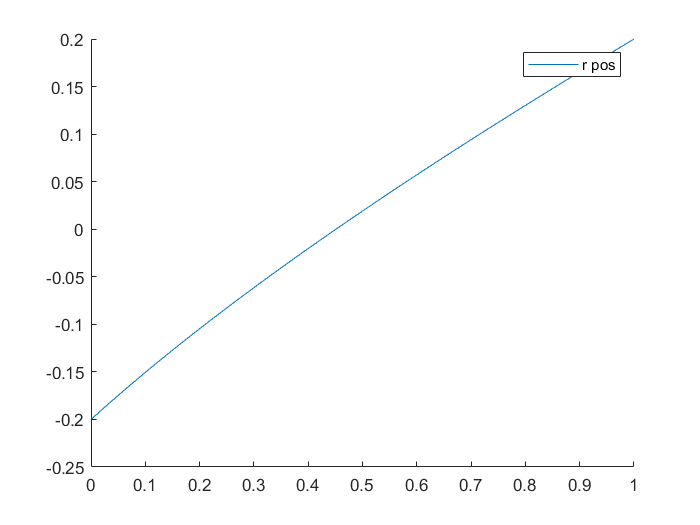

figure()
clf;
hold on

for i=1:n
    X = posArray(i).phiZ;
    Xr(i) = X(1) ;
    %Xz(i) = X(2);
end
plot(t,Xr)
%plot(t,Xz)
legend("r pos","z pos")

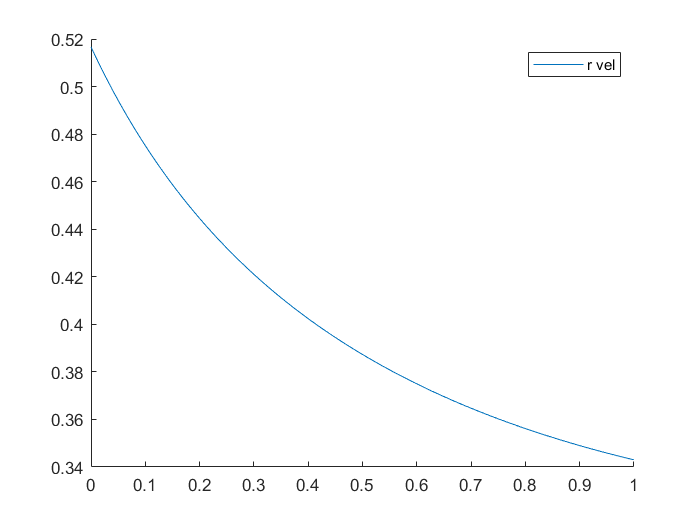


figure()
clf;
hold on
for i=1:n-1
    V = v(i).dphiZ;
    Vr(i) = V(1) ;
    %Vz(i) = V(2);
end
plot(t(1:n-1),Vr)
%plot(t(1:n-1),Vz)
legend("r vel","z vel")

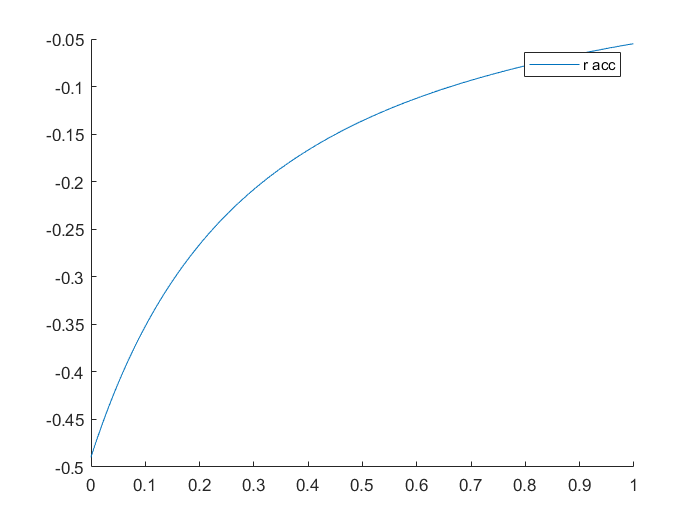


figure()
clf;
hold on

for i=1:n-2
    A = a(i).ddphiZ;
    Ar(i) = A(1) ;
    %Az(i) = A(2);
end


plot(t(1:n-2),Ar)
%plot(t(1:n-2),Az)
legend("r acc","z acc")